# Coursework - Control System

Student Name: ___________________

Student ID: ______________________

## Part a: State Space Model

Create a non-linear state space model, considering:

clear;
clc;

% System parameters
m = 0.05;    % mass of the ball, kg
g = 9.8;    % the acceleration due to gravity, m/s^2
L = 0.01;    % inductance of the coil, H
R = 1;         % Resistance, ohms
K = 0.0001;     % coefficient that determines the magnetic force exerted on the ball
y_0 = 0.01;    % operating point, m

% state space matrix 

A = [-R/L 0 0;
    0 0 1;
    -2*sqrt((g*K)/(m*y_0)) (g/y_0) 0]

A =  -100.0000         0         0
         0         0    1.0000
   -2.8000  980.0000         0


B = [1/L; 0; 0]

B =    100
     0
     0


C = [0 1 0]

C =      0     1     0


D = 0;

% MATLAB command to create a state space model
state_space_model = ss(A, B, C, D)


state_space_model =
 
  A = 
         x1    x2    x3
   x1  -100     0     0
   x2     0     0     1
   x3  -2.8   980     0
 
  B = 
        u1
   x1  100
   x2    0
   x3    0
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


## Part b: Transfer Function

Determine the transfer function of the system, controlling height ℎ of the suspended ball. Consider the linearized model given in the appendix.

% Transfer function of the system
% commands to get the transfer function



## Part c

Analyze the open loop response of the plant in terms of stability using MATLAB. Show necessary plots.

% Open loop step response 
% commands to get step response




[Simulink Model for step response](matlab:open('./StepResponse.slx'))

## Part d

Discuss observability and controllability using MATLAB.

% Controllability




% Observability



## Part e

Design a state feedback controller (the reasonable design criteria specification is up to you). (MATLAB/SIMULINK)

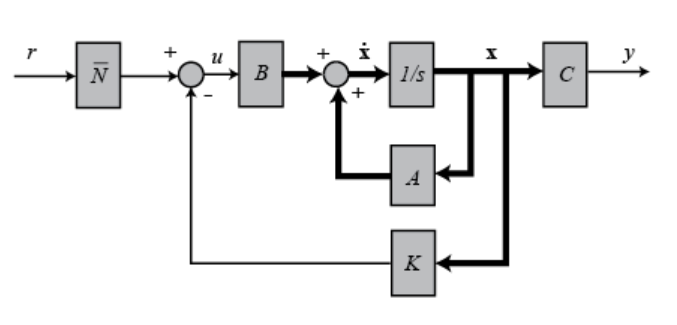

% Determining gain K matrix using pole placement




% state feedback controller



[Full State Feedback Controller Simulink](matlab:open('./FullStateFeedbackController.slx'))

## Part f

Design a corresponding observer and explain when it will be used. (MATLAB/SIMULINK)

% Observer Design





## Conclusion

## References